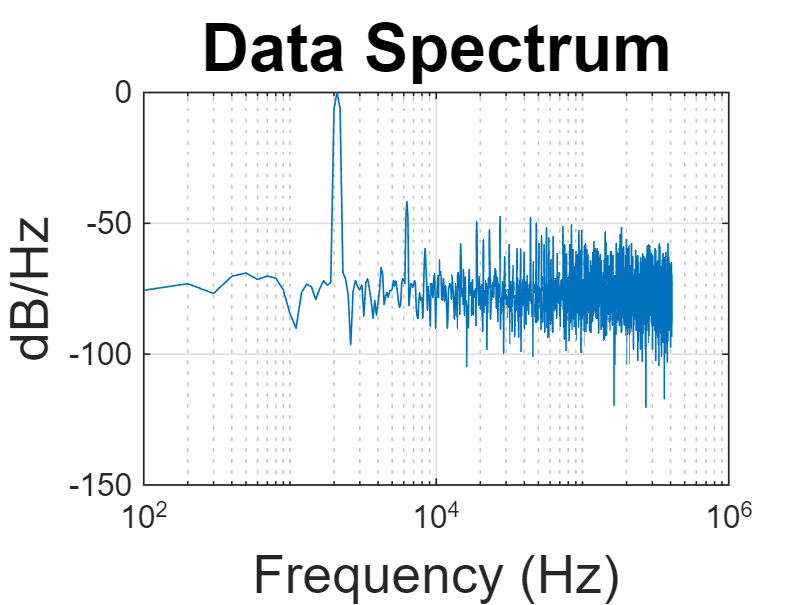

@Freq = 2100.000, SNR = 35.458 dB, SNDR = 34.510 dB, SFDR = 41.737 dB, HD2 = 66.911 and HD3 = 41.737


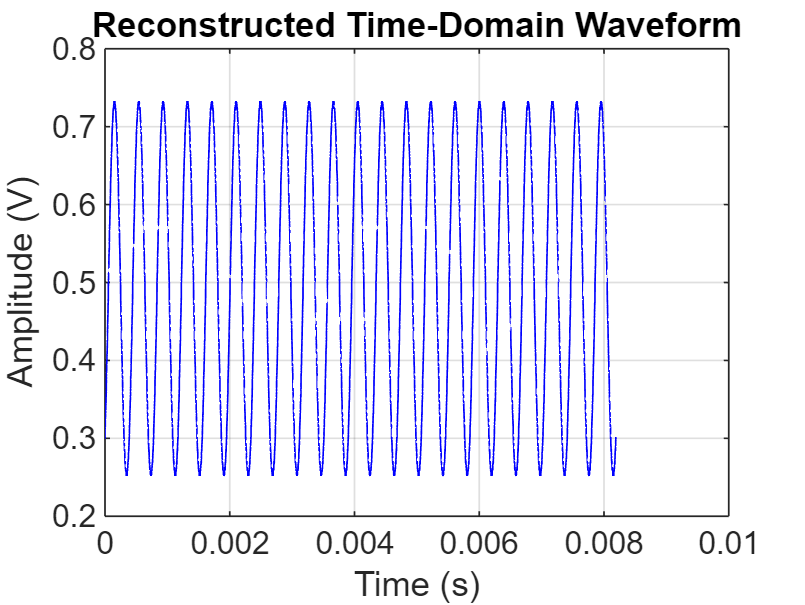

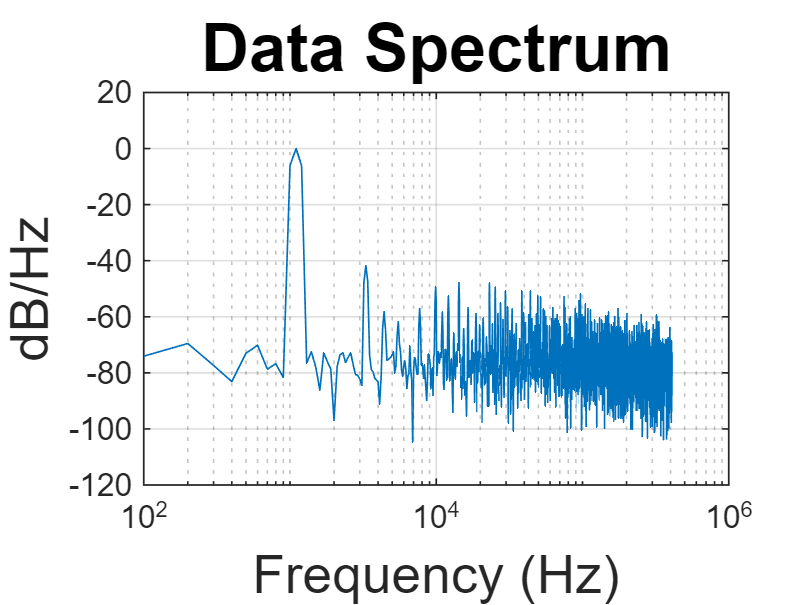

@Freq = 1100.000, SNR = 35.463 dB, SNDR = 34.501 dB, SFDR = 41.697 dB, HD2 = 73.490 and HD3 = 41.697


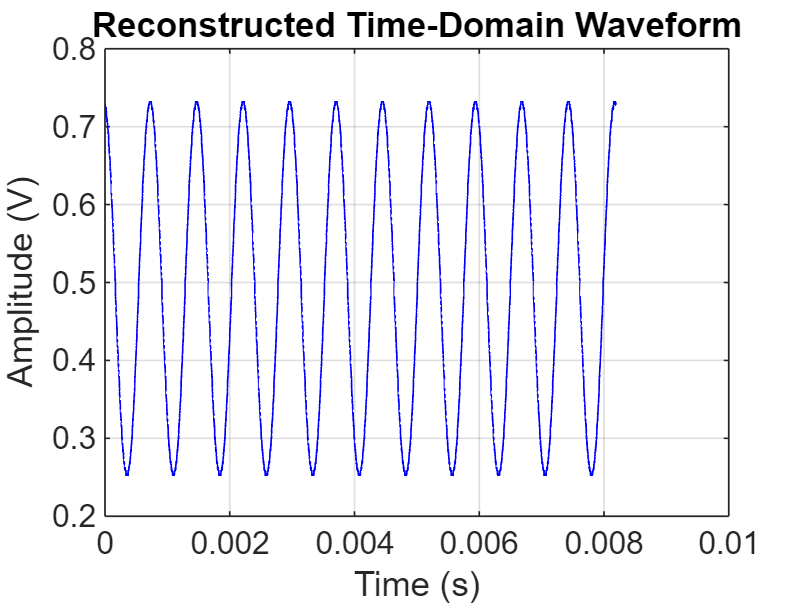

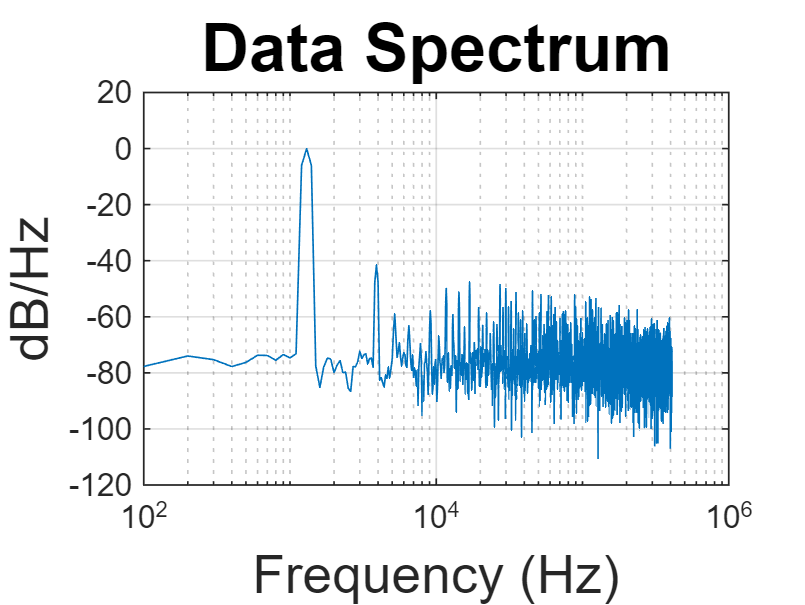

@Freq = 1300.000, SNR = 35.461 dB, SNDR = 34.495 dB, SFDR = 41.615 dB, HD2 = 86.702 and HD3 = 41.615


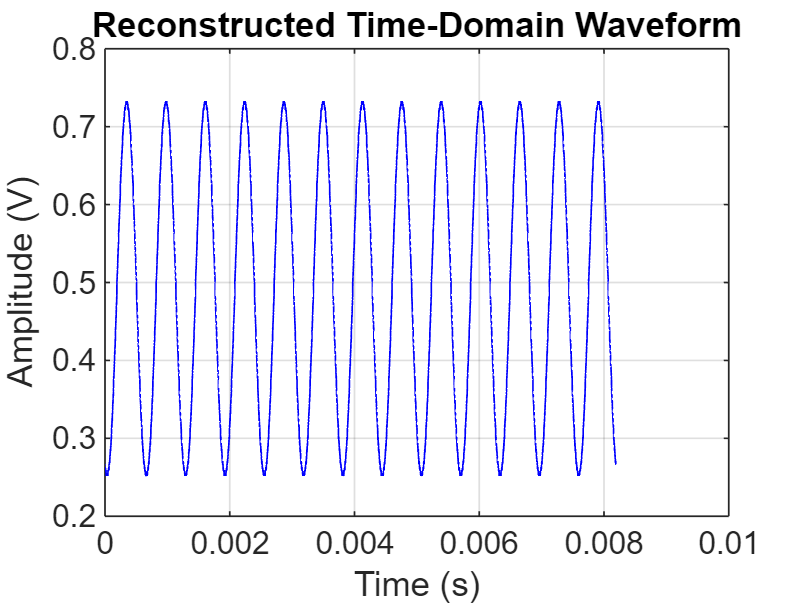

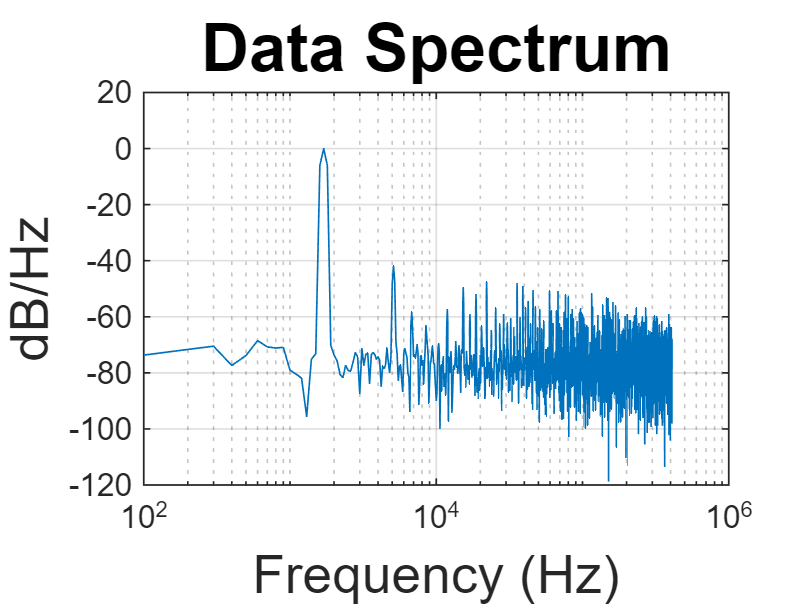

@Freq = 1700.000, SNR = 35.331 dB, SNDR = 34.421 dB, SFDR = 41.810 dB, HD2 = 72.883 and HD3 = 41.810


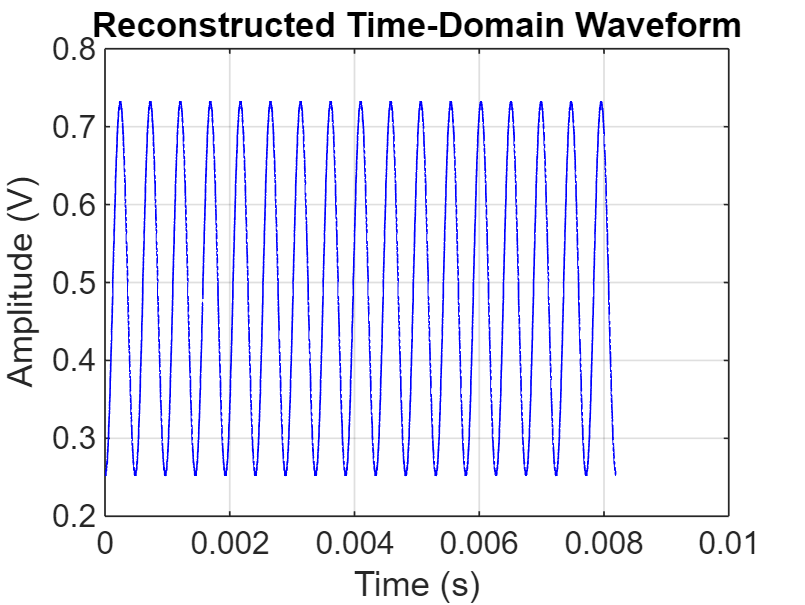

@Freq = 2100.000, SNR = 35.458 dB, SNDR = 34.510 dB, SFDR = 41.737 dB, HD2 = 66.911 and HD3 = 41.737


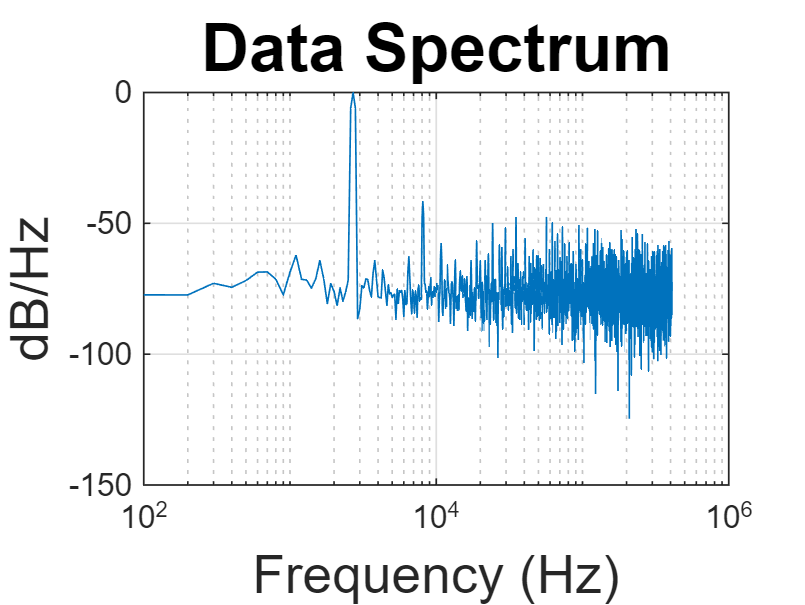

@Freq = 2700.000, SNR = 35.496 dB, SNDR = 34.514 dB, SFDR = 41.600 dB, HD2 = 75.141 and HD3 = 41.600


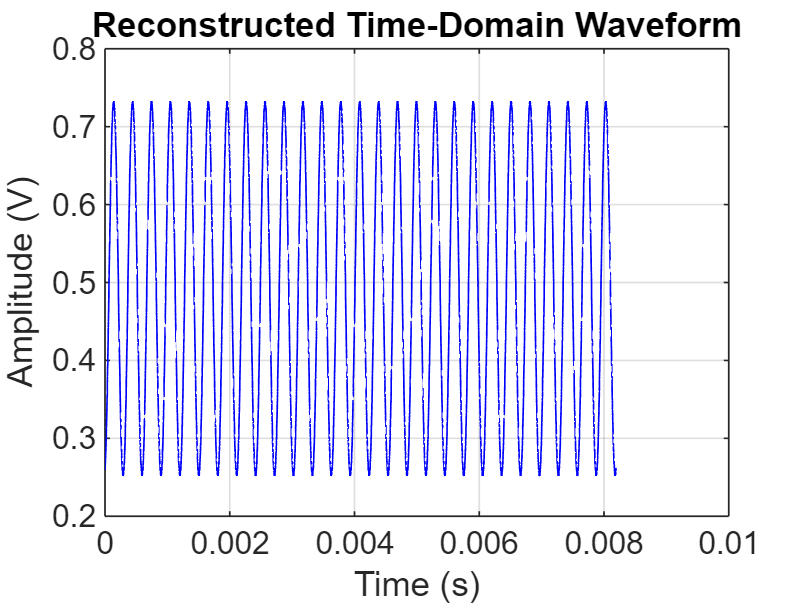

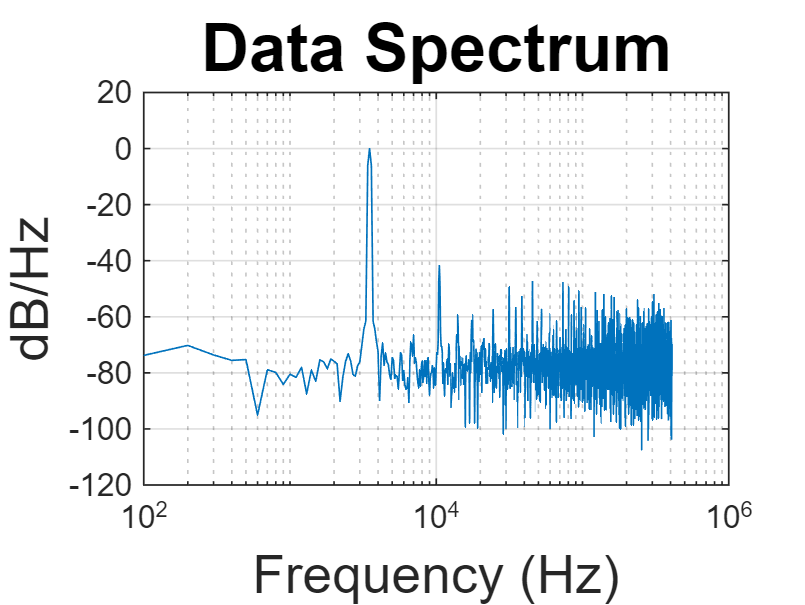

@Freq = 3500.000, SNR = 35.576 dB, SNDR = 34.577 dB, SFDR = 41.669 dB, HD2 = 66.355 and HD3 = 41.669


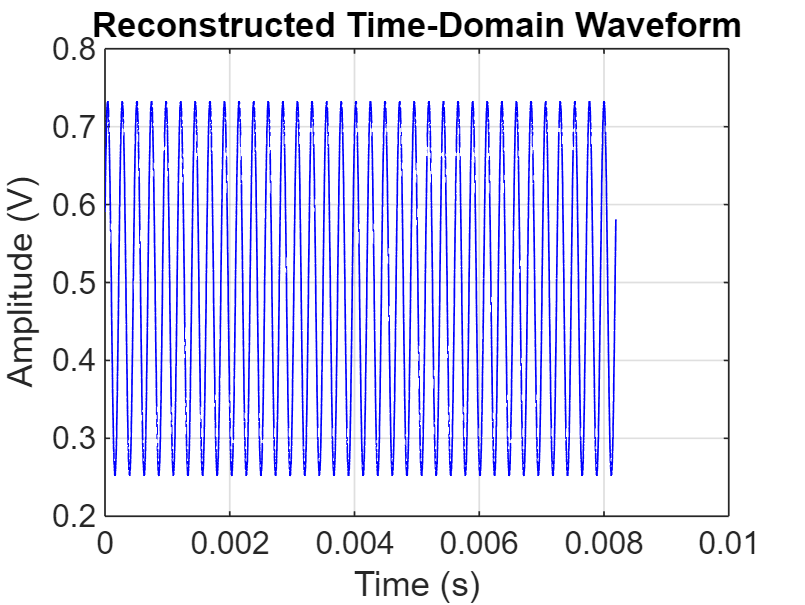

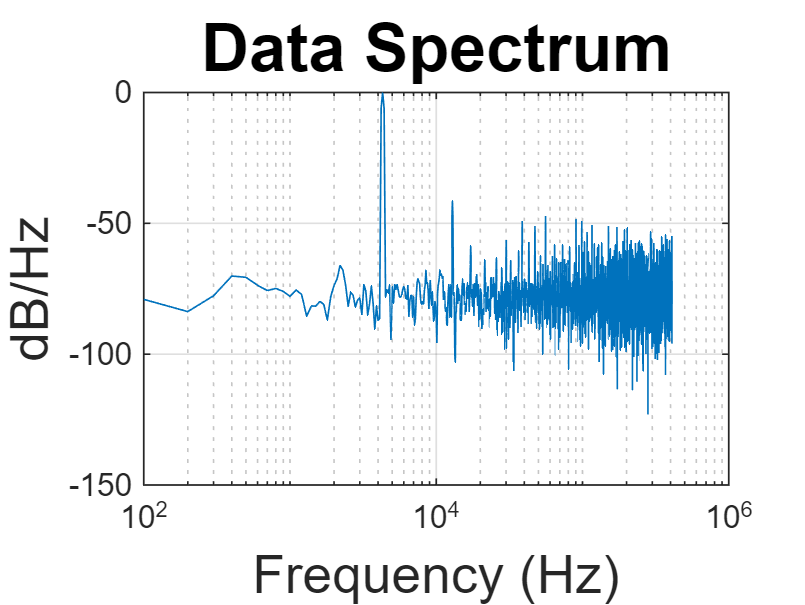

@Freq = 4300.000, SNR = 35.503 dB, SNDR = 34.514 dB, SFDR = 41.567 dB, HD2 = 73.032 and HD3 = 41.567


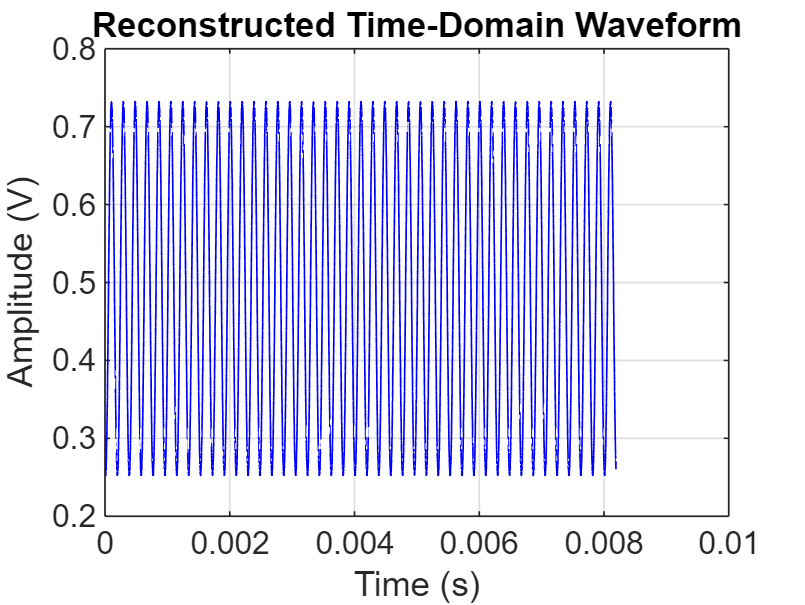

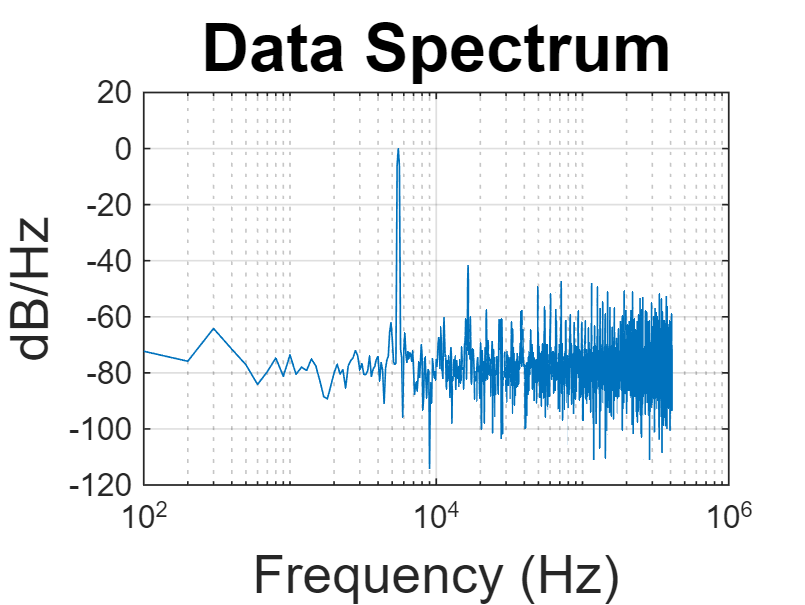

@Freq = 5500.000, SNR = 35.461 dB, SNDR = 34.528 dB, SFDR = 41.783 dB, HD2 = 79.373 and HD3 = 41.783


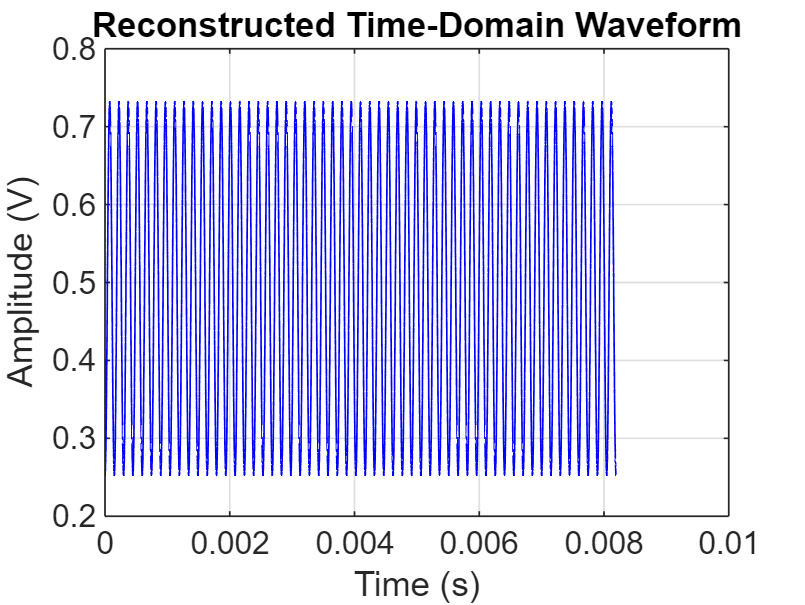

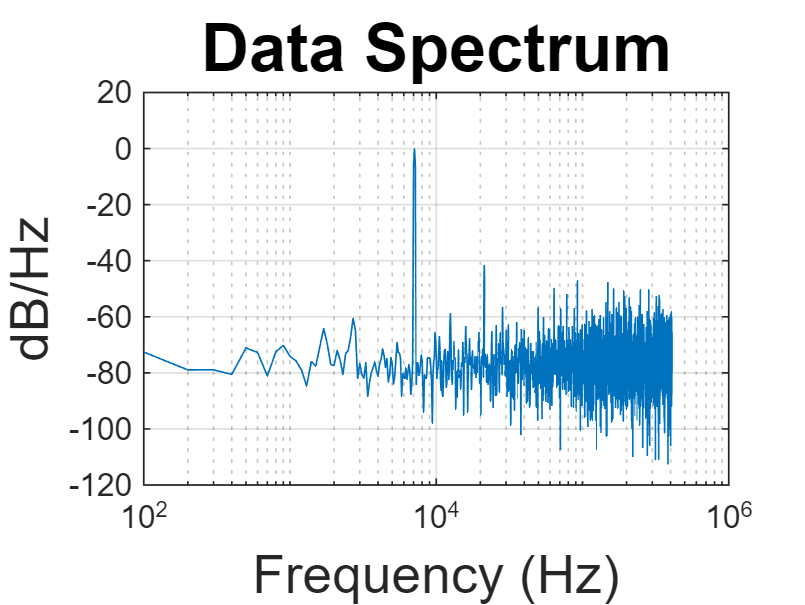

@Freq = 7100.000, SNR = 35.440 dB, SNDR = 34.467 dB, SFDR = 41.648 dB, HD2 = 71.836 and HD3 = 41.648


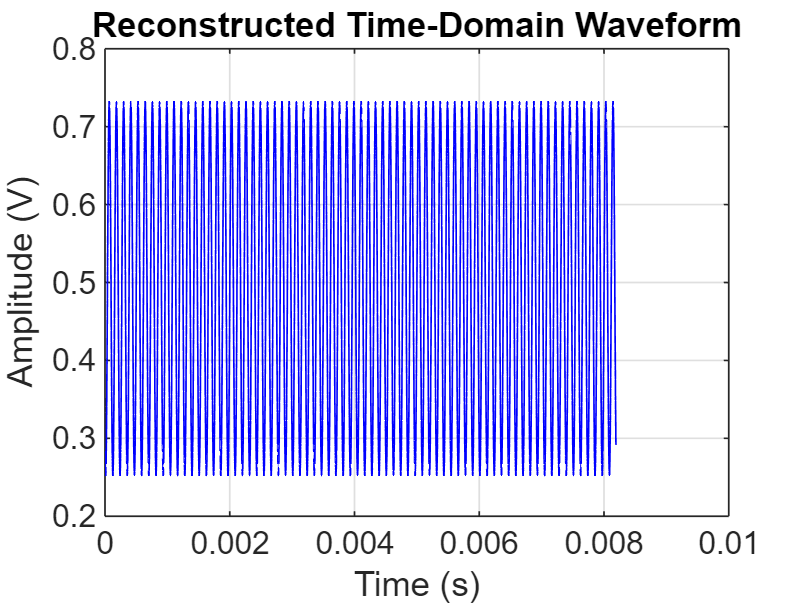

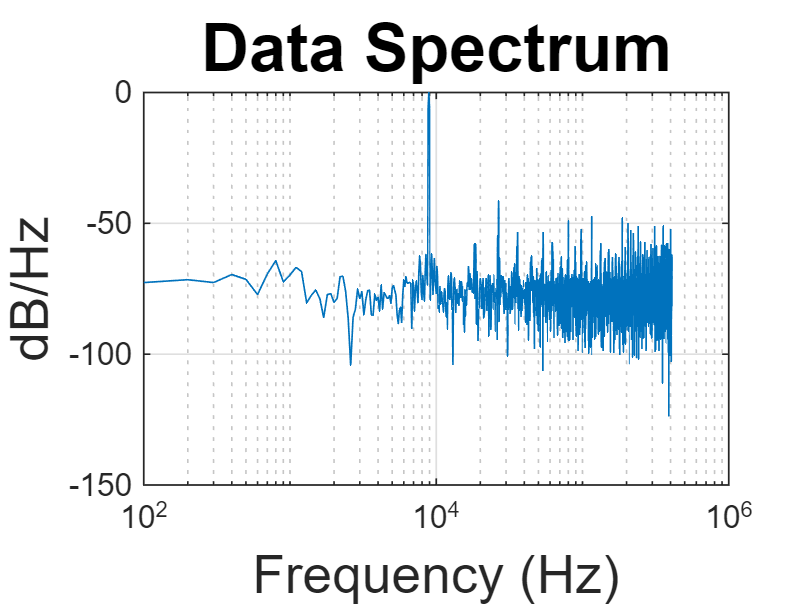

@Freq = 8900.000, SNR = 35.451 dB, SNDR = 34.458 dB, SFDR = 41.470 dB, HD2 = 74.652 and HD3 = 41.470


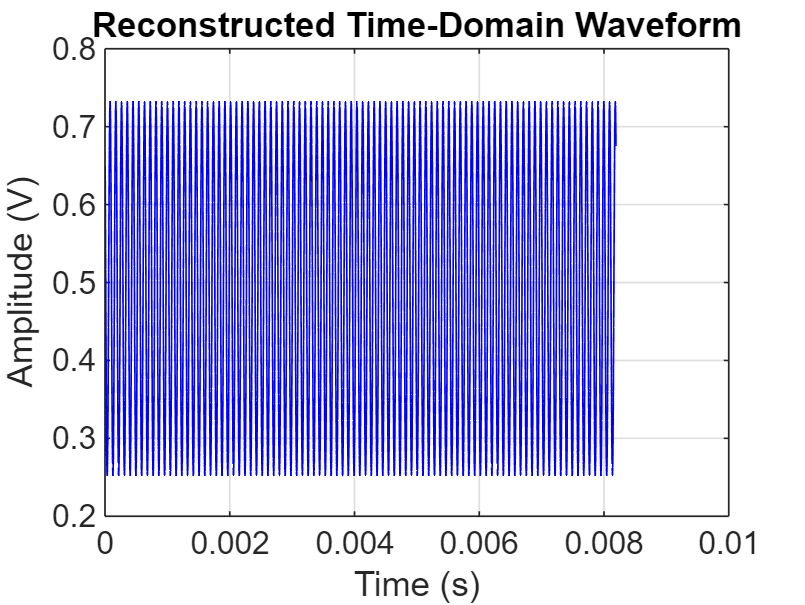

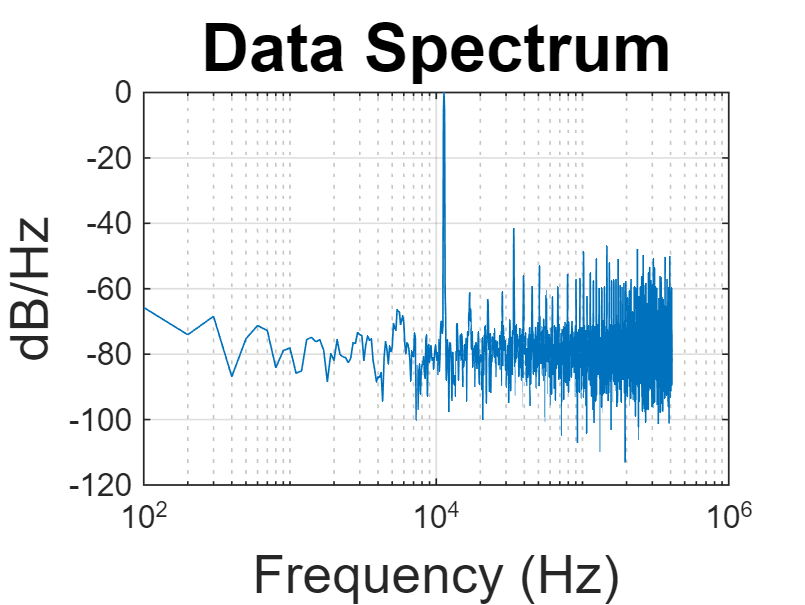

@Freq = 11300.000, SNR = 35.654 dB, SNDR = 34.595 dB, SFDR = 41.584 dB, HD2 = 63.925 and HD3 = 41.584


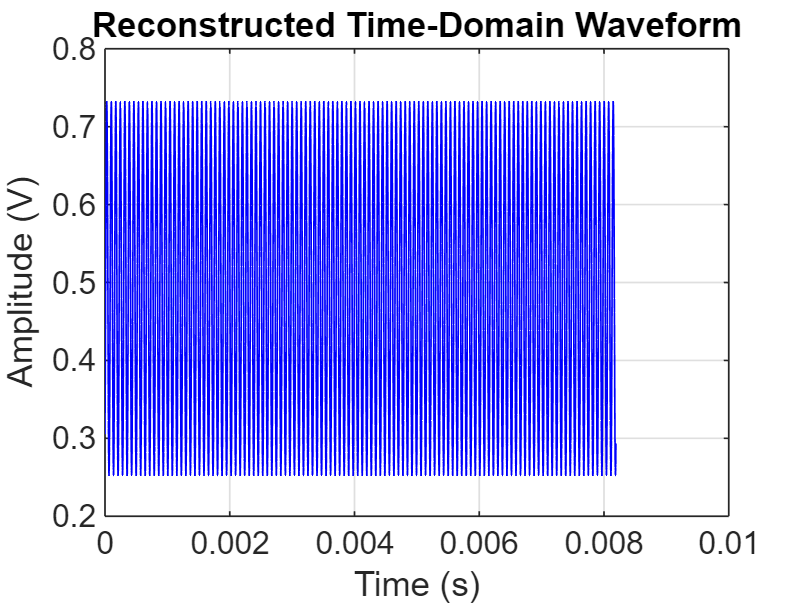

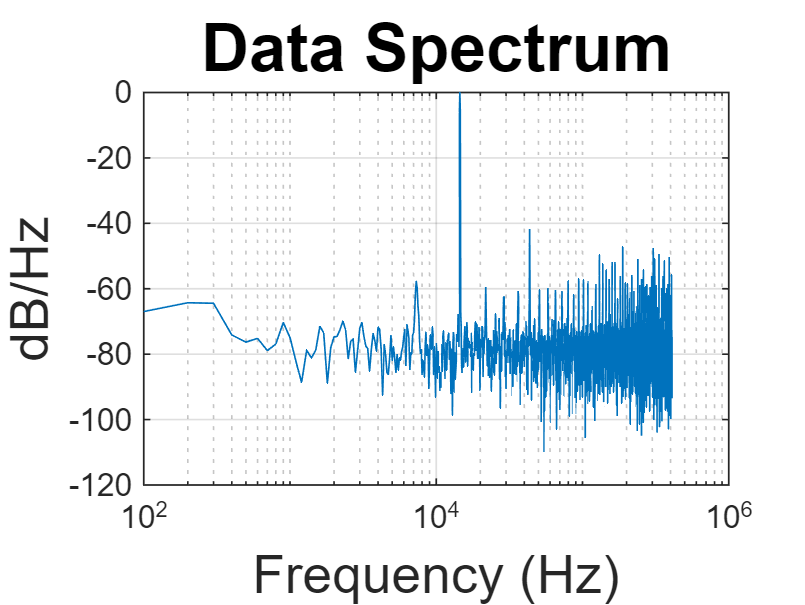

@Freq = 14500.000, SNR = 35.520 dB, SNDR = 34.532 dB, SFDR = 41.860 dB, HD2 = 62.496 and HD3 = 41.860


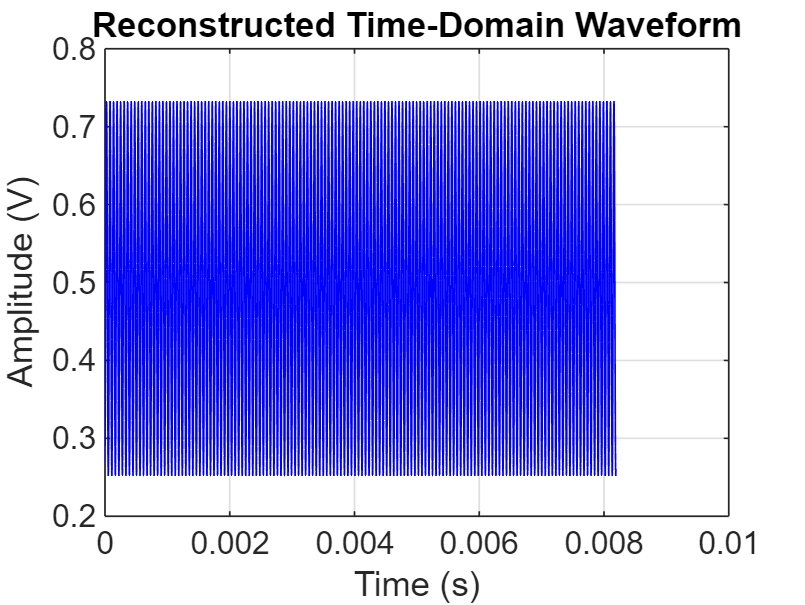

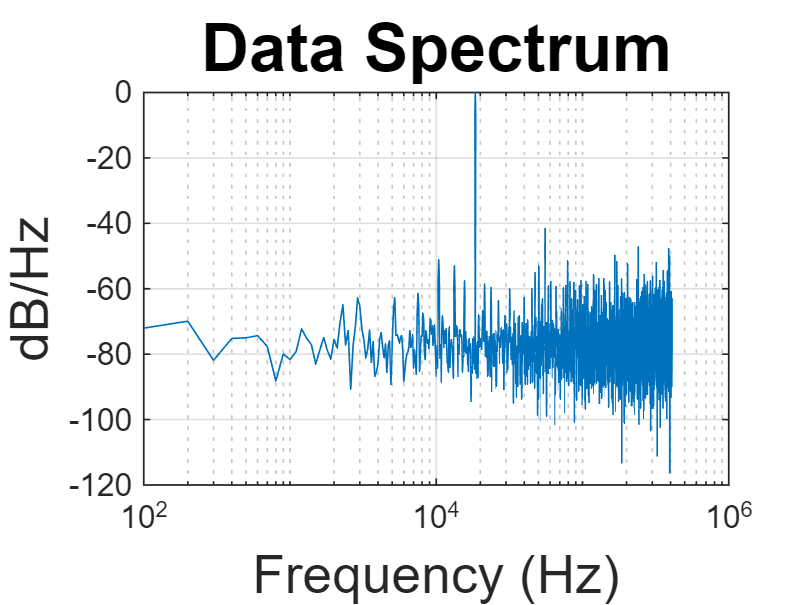

@Freq = 18500.000, SNR = 35.486 dB, SNDR = 34.526 dB, SFDR = 41.660 dB, HD2 = 68.315 and HD3 = 41.660


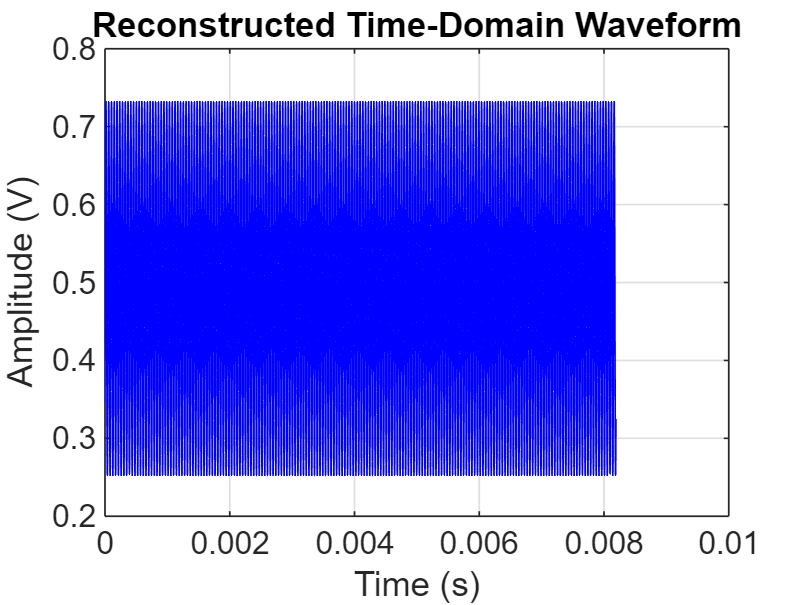

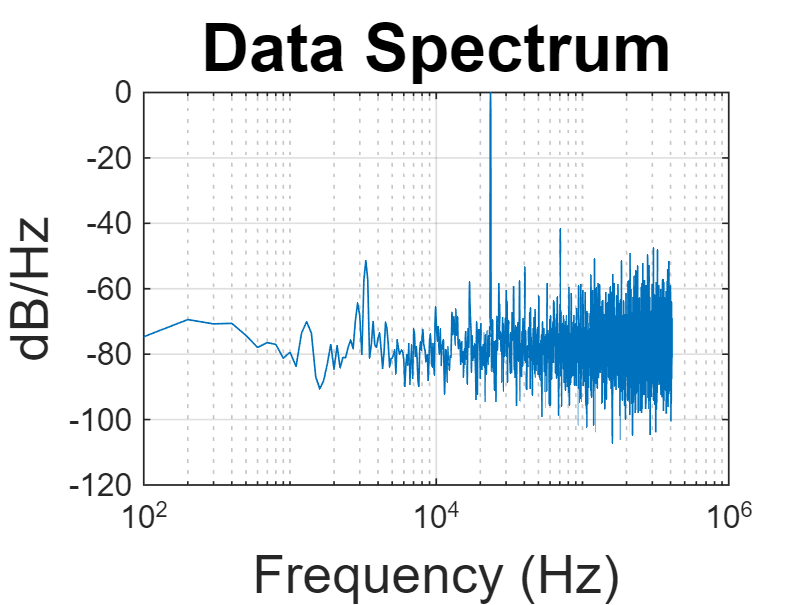

@Freq = 23500.000, SNR = 35.433 dB, SNDR = 34.486 dB, SFDR = 41.678 dB, HD2 = 70.406 and HD3 = 41.678


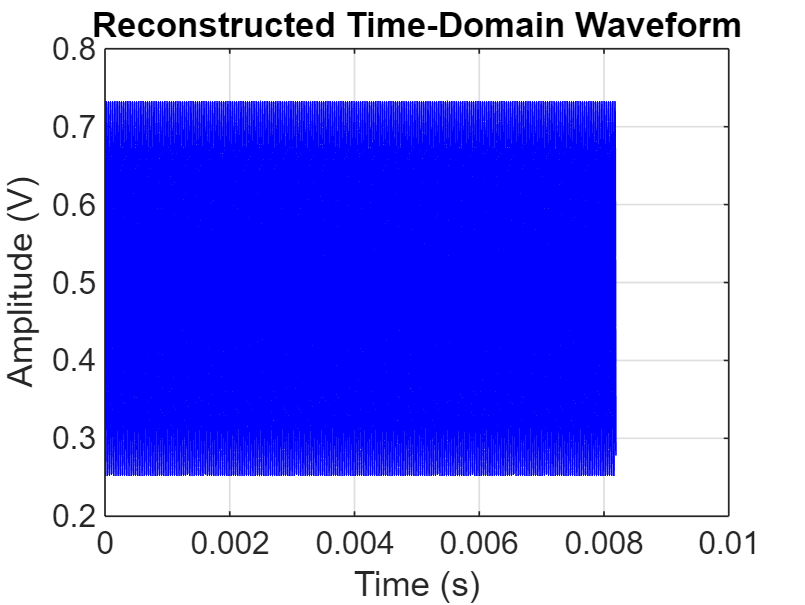

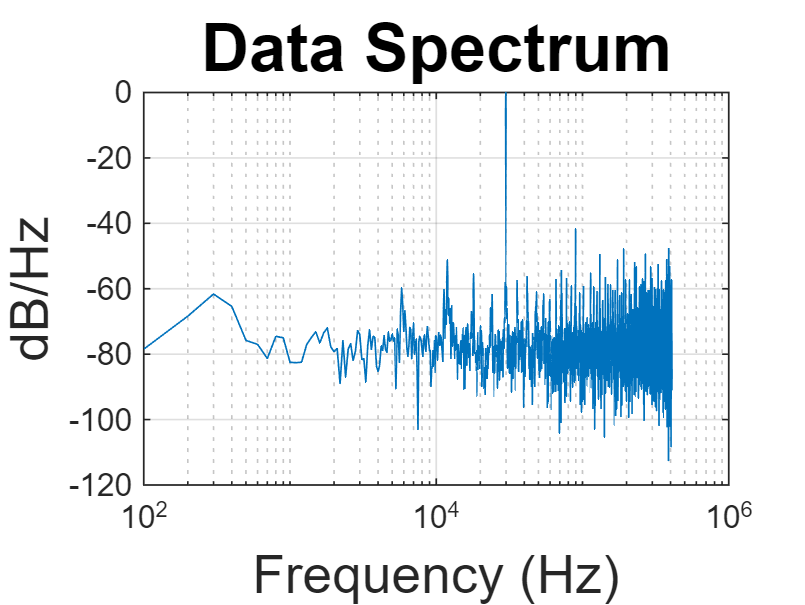

@Freq = 29900.000, SNR = 35.444 dB, SNDR = 34.493 dB, SFDR = 41.720 dB, HD2 = 63.240 and HD3 = 41.720


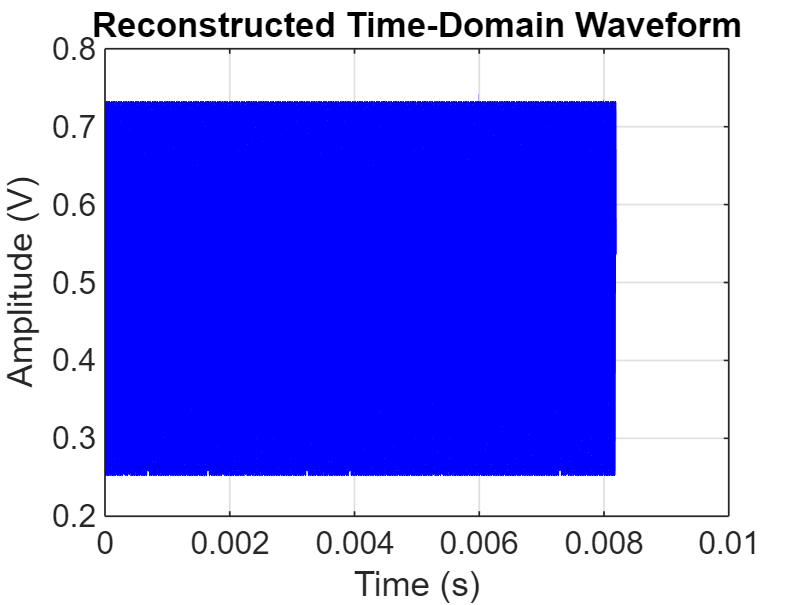

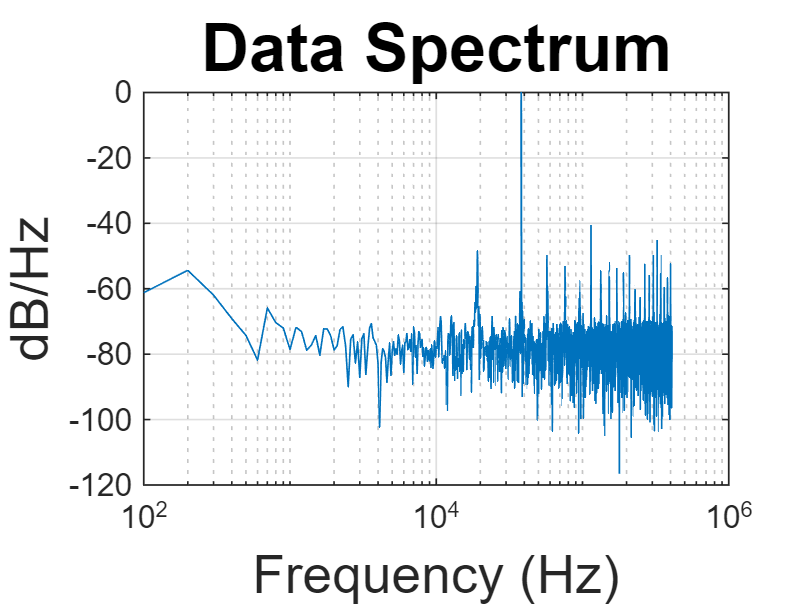

@Freq = 38100.000, SNR = 35.635 dB, SNDR = 34.065 dB, SFDR = 40.690 dB, HD2 = 58.028 and HD3 = 40.690


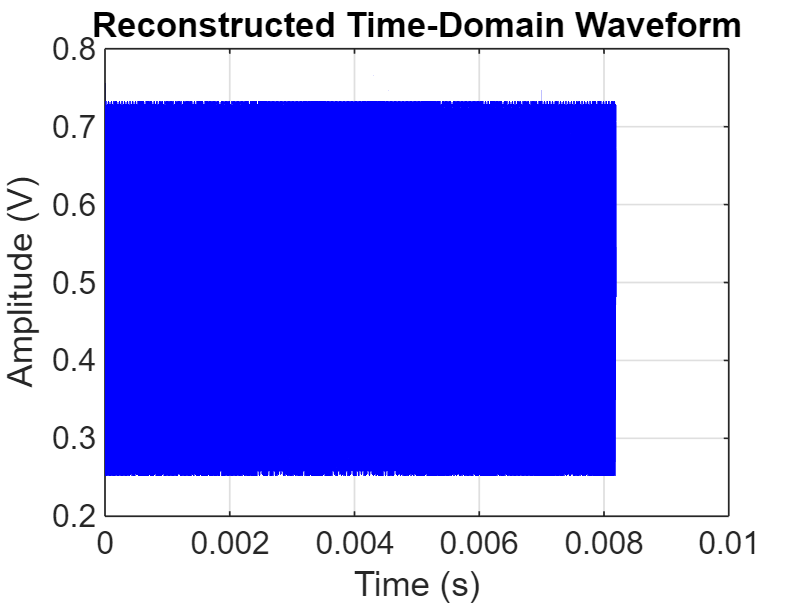

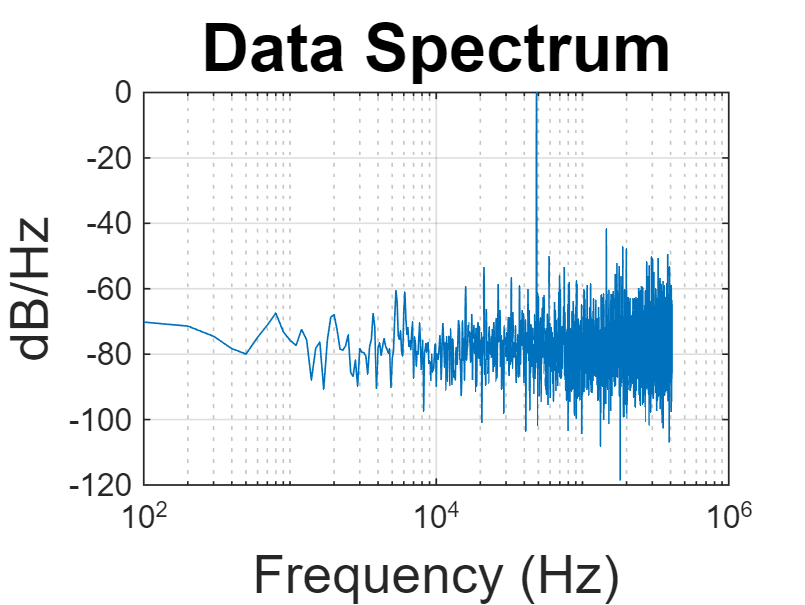

@Freq = 48500.000, SNR = 35.477 dB, SNDR = 34.532 dB, SFDR = 41.745 dB, HD2 = 69.806 and HD3 = 41.745


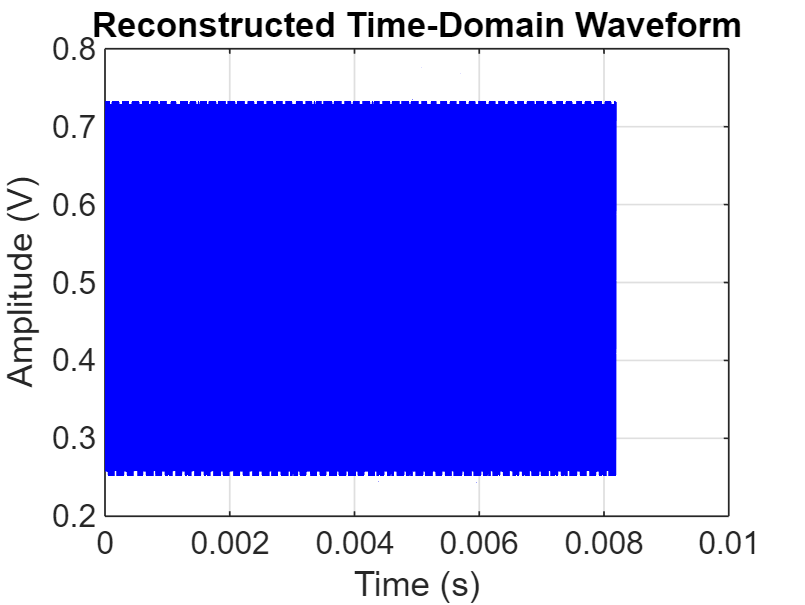

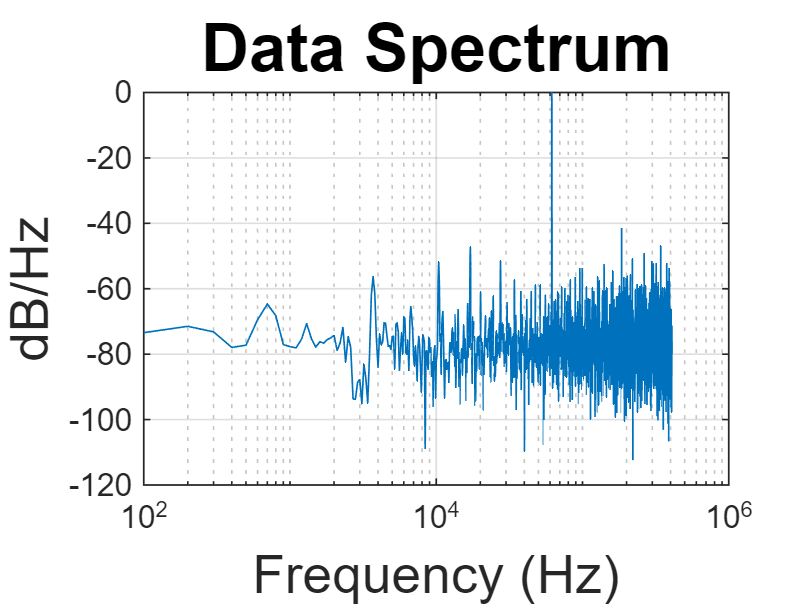

@Freq = 61700.000, SNR = 35.442 dB, SNDR = 34.447 dB, SFDR = 41.530 dB, HD2 = 68.652 and HD3 = 41.530


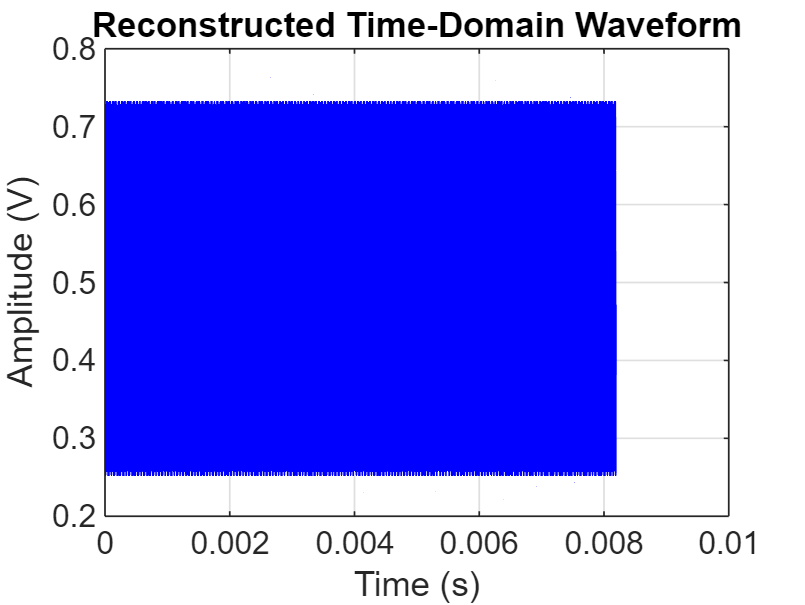

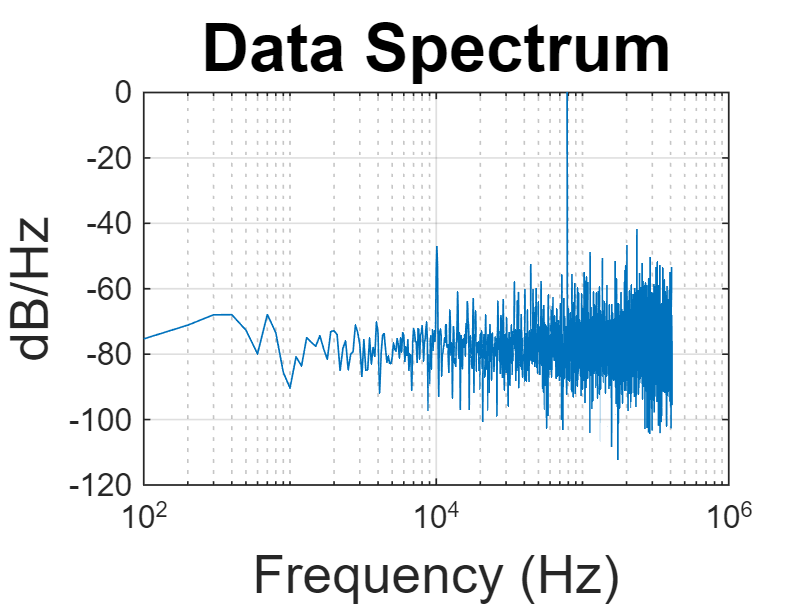

@Freq = 78500.000, SNR = 35.371 dB, SNDR = 34.467 dB, SFDR = 41.842 dB, HD2 = 69.289 and HD3 = 41.842


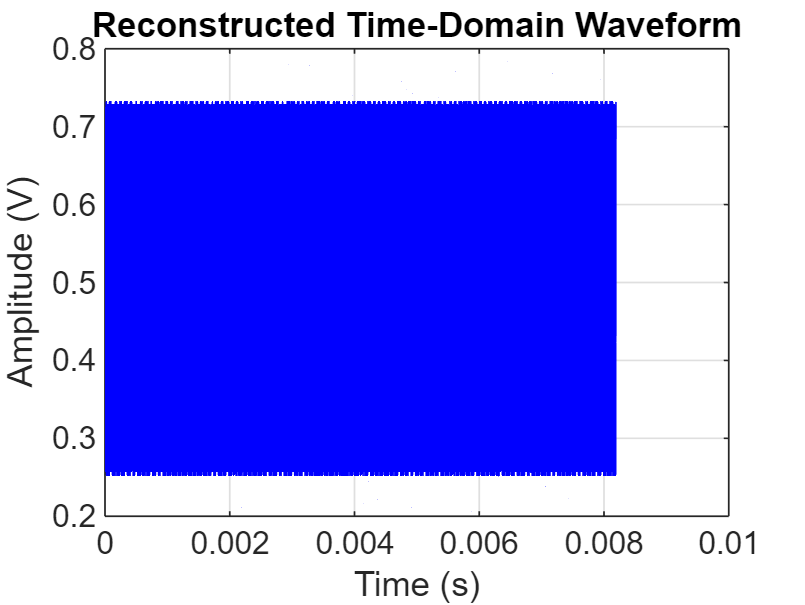

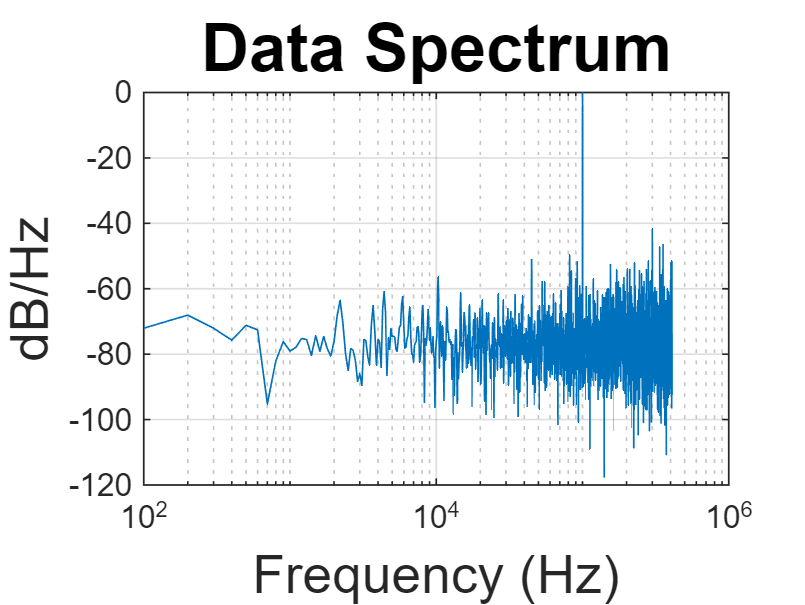

@Freq = 100100.000, SNR = 35.385 dB, SNDR = 34.461 dB, SFDR = 41.748 dB, HD2 = 71.804 and HD3 = 41.748


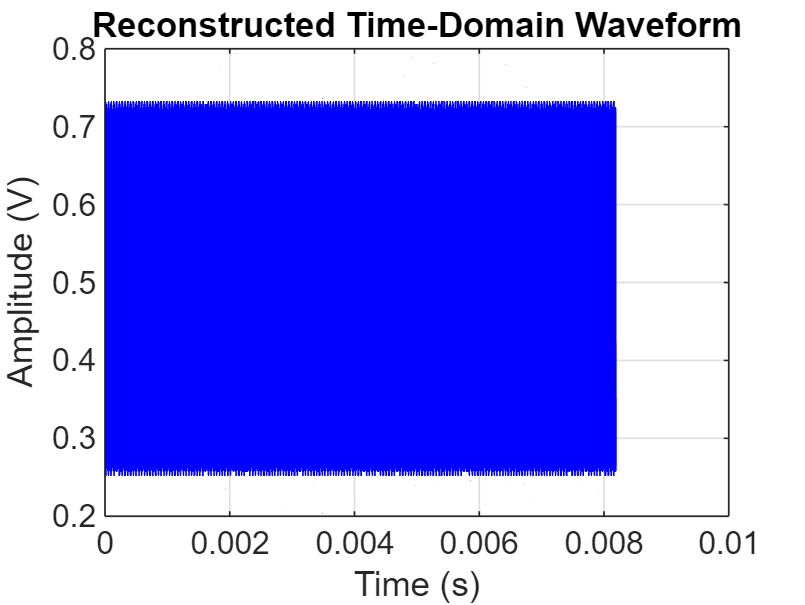

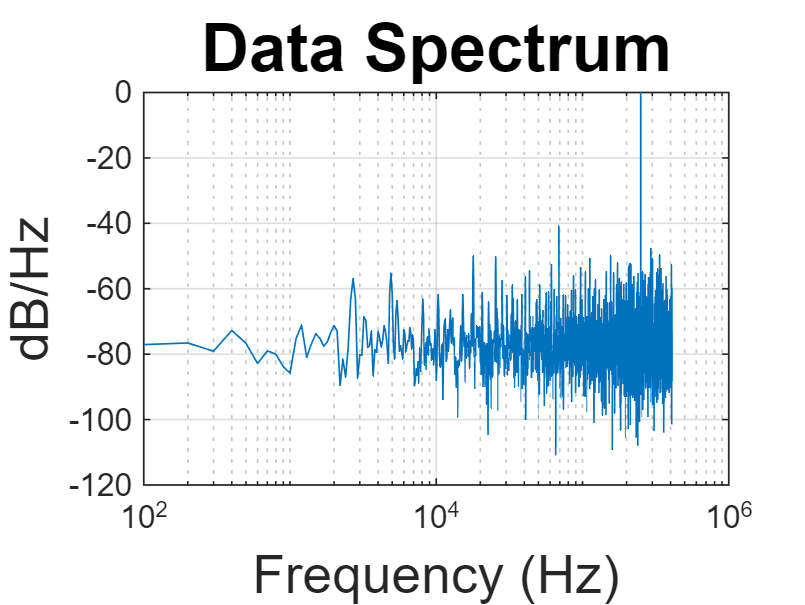

@Freq = 250100.000, SNR = 34.037 dB, SNDR = 34.035 dB, SFDR = 40.874 dB, HD2 = 62.535 and HD3 = 40.874


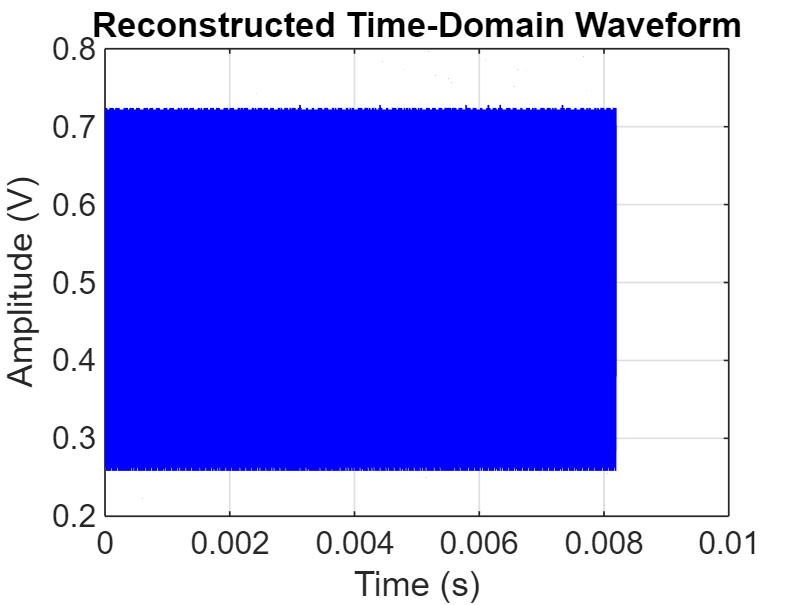

clearvars
freq_array = readtable('./ADC_Data/Kaishi-Data/EthanTB-Board3_12-1-SEDE-Freq_1k_250k-SIN_1000mV-CLK_0MHz_Duty50%/freq_array.csv');
freq_array = table2array(freq_array);
freq_array = floor(freq_array);
%%% Remember to change this! if folder change
filepath = './ADC_Data/Kaishi-Data/EthanTB-Board3_12-1-SEDE-Freq_1k_250k-SIN_1000mV-CLK_0MHz_Duty50%/';
% 1:freq, 2: SNR, 3: SNDR 4:SFDR
BigSet = zeros(length(freq_array),4);
% :length(freq_array)
for i = 1:length(freq_array)
    freq = num2str(freq_array(i));
    BigSet(i,1) = freq_array(i);
    filename = strcat(filepath,'SIN_',num2str(freq_array(i)),'.0Hz_.csv');
    data = readtable(filename);
    data_dec = table2array(data);
    % data_dec = data_dec(data_dec ~= 0);
    data_bin = dec2bin(data_dec);
    data_EOC = str2num(data_bin(:,1));
    data_Code = str2num(data_bin(:,2:10));
    data_NewCode = size(length(data_Code),1);
    data_Code_dec = bin2dec(num2str(data_Code));
    rising_edge_indices = find(diff(data_EOC) == 1)+1;
    
    for k = 1:length(rising_edge_indices)
        index = rising_edge_indices(k);
        data_NewCode(k,1) = data_Code_dec(index); 
    end

    data_NewDec = data_NewCode;

    Fs=819.2e3;
    num_segments=1;
    f_signal = freq_array(i);
    f_s = Fs;
    BW =Fs/2;
    sample_size=length(data_NewDec);
    periodogram_length = sample_size / num_segments;
    fbin = f_s / periodogram_length;
    plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
        plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
        f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    set(gcf,'color','w')
    BigSet(i,2) = SNR;
    BigSet(i,3) = SNDR;
    BigSet(i,4) = SFDR;
    
    %%%%%% Reconstructed the waveform
    % Parameters
    fs = 1e6;                 % Sampling rate in Hz
    N = length(data_NewDec);                  % Number of samples
    bit_depth = 9;            % ADC bit resolution
    V_min = 0;              % Minimum input voltage
    V_max = 1;               % Maximum input voltage
    
    % Map codes to voltage
    voltages = ((data_NewDec / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;
    
    % Create time axis
    t = (0:N-1) / fs;
    
    % Plot the reconstructed waveform
    figure;
    plot(t, voltages, 'b');
    title('Reconstructed Time-Domain Waveform');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

save('BigSet.mat', 'BigSet');

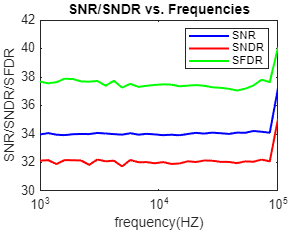

save('BigSet.mat', 'BigSet');
load('BigSet.mat')
figure
semilogx(BigSet(:,1), BigSet(:,2), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(BigSet(:,1), BigSet(:,3), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
semilogx(BigSet(:,1), BigSet(:,4), 'g-', 'LineWidth', 1.5, "DisplayName","SFDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR/SFDR");
title("SNR/SNDR vs. Frequencies");
legend;